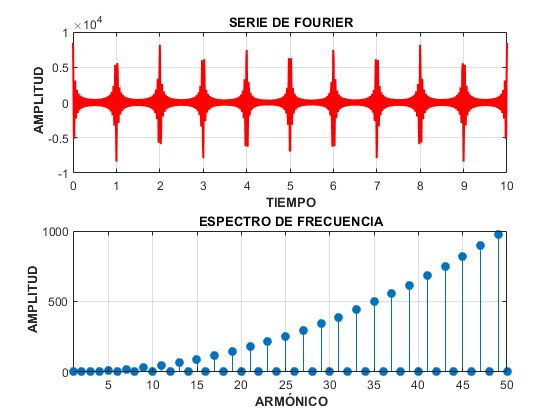

%Programa para generar las gráficas de la serie de Fourier así como su espectro y componentes

%% Series de Fourier
clc
clear
close all
 
syms n t
  
Ao=1/2;
An=(5/(8*pi^(2)*n^(2)))*(8*pi*n/5*sin(7*pi*n/5)+cos(7*pi*n/5)-cos(pi*n/5)); 
Bn=(5/(8*pi^(2)*n^(2)))*(sin(7*pi*n/5)+sin(pi*n/5)-8*pi*n/5*cos(7*pi*n/5));
T=2;

wo=2*pi/T;
 
Arm=20;
 
for n=1:Arm
   f(n,:)=sum((2/pi^(2)*n^(2))*(1-cos(pi*n)))*cos(n*wo*t)+(0)*sin(n*wo*t);
end
t=linspace(0,5*T,1000);
f=subs(f,'t',t);
f(n+1,:)=zeros(1,1000);
plot(t,Ao+sum(f),'Linewidth',2); grid on
xlabel('\bf TIEMPO'); ylabel('\bf AMPLITUD');  
title('\bf SERIES DE FOURIER');
 
%% SERIES DE FOURIER ANIMADA
clc
clear
close all
syms n t
 
Ao=1/2;
An=(5/(8*pi^(2)*n^(2)))*(8*pi*n/5*sin(7*pi*n/5)+cos(7*pi*n/5)-cos(pi*n/5)) ;
Bn=(5/(8*pi^(2)*n^(2)))*(sin(7*pi*n/5)+sin(pi*n/5)-8*pi*n/5*cos(7*pi*n/5));
T=2;

wo=2*pi/T;
 
Arm=50;
 
for n=1:Arm
    syms t
    f(n,:)=sum(((2/pi^(2)*n^(2))*(1-cos(pi*n)))*cos(n*wo*t)+(0)*sin(n*wo*t));
    t=linspace(0,5*T,1000);
   
% subplot(3,1,1);
% plot(t, subs(f(n,:),'t',t)); grid on
% xlabel('\bf TIEMPO'); ylabel('\bf AMPLITUD');  
% title('\bf COMPONENTE'); hold on
%  
subplot(2,1,1);
plot(t, Ao+subs(sum(f),'t',t), 'r', 'Linewidth',1.5); grid on
xlabel('\bf TIEMPO'); ylabel('\bf AMPLITUD');  
title('\bf SERIE DE FOURIER')
 
subplot(2,1,2);
Cn(n)=sqrt(((2/pi^(2)*n^(2))*(1-cos(pi*n)))^2+((5/(8*pi^(2)*n^(2))))*(0)^2);
stem(Cn,'fill'); grid on
xlim([1,Arm]);
xlabel('\bf ARMÓNICO'); ylabel('\bf AMPLITUD');  
title('\bf ESPECTRO DE FRECUENCIA');
end